## AAE 440 PS9 Problem 2

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE440\MATLAB\outputs\HW9';
set(groot, 'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');
rgb = linspecer(70);

% Defining System Properties
I       = 400;              % transverse moment of inertia [kg m2] 
J       = 100;              % axial moment of inertia      [kg m2] 
gamma0  = 8;                % Initial perturbation  [deg]
rev     = 0:0.001:2;        % Integration revolutions

% spin factor
k0      = [-15 6 12 30 80]; 
k       = [-15 6 12 30 80 100]; 

### (a)

% Iteration for different spin factors
for i = 1:length(k)-1
    % Nutation and Precession History
    [rev, Nut, Prec] = Nut_Prec_History(rev,k(i),gamma0,I,J);
    % Plot Gammas
    fig1 = figure(1);
        hold on;
        plot(rev, Nut, 'DisplayName',['k = ',num2str(k(i))])
    % Plot Sigmas
    sigma = 360*rev;
    fig2 = figure(2);
        hold on;
        plot(rev, sigma, 'DisplayName',['k = ',num2str(k(i))])
    % Plot Alphas
    fig3 = figure(3);
        hold on;
        plot(rev, Prec, 'DisplayName',['k = ',num2str(k(i))])   
    % Plot Betas
    beta = Prec+sigma;
    fig4 = figure(4);
        hold on;
        plot(rev, beta, 'DisplayName',['k = ',num2str(k(i))])
end

% Saving Figures
for i = 1:4
    fig = figure(i);
        grid on; grid minor; box on; legend; xlabel('Revolutions');
        switch i
            case 1
                ylabel('Nutation Angle $\gamma$ [deg]')
                title({'Nutation Angle History, Koike'})
                saveas(fig, fullfile(fdir, 'P2a_Nutation_History.png'));
            case 2
                ylabel('Sigma Angle $\sigma$ [deg]')
                title({'Sigma Angle History, Koike'})
                saveas(fig, fullfile(fdir, 'P2a_Sigma_History.png'));
            case 3
                ylabel('Precession Angle $\alpha$ [deg]')
                title({'Precession Angle History, Koike'})
                saveas(fig, fullfile(fdir, 'P2a_Precession_History.png'));
            case 4
                ylabel('Beta Angle $\beta$ [deg]')
                title({'Beta Angle History, Koike'})
                saveas(fig, fullfile(fdir, 'P2a_Beta_History.png'));
        end
end

% Add k = 100 case to figures
% Nutation and Precession History
[rev, Nut, Prec] = Nut_Prec_History(rev,k(end),gamma0,I,J);
% Plotting Gammas
figure(1);
    hold on;
    plot(rev, Nut, 'DisplayName',['k = ',num2str(k(end))])
% Plotting Sigmas
sigma = 360*rev;
figure(2);
    hold on;
    plot(rev, sigma, 'DisplayName',['k = ',num2str(k(end))])
% Plotting Alphas (Precession)
figure(3);
    hold on;
    plot(rev, Prec, 'DisplayName',['k = ',num2str(k(end))])   
% Plotting Betas (Inertial Precession)
beta = Prec+sigma;
figure(4);
    hold on;
    plot(rev, beta, 'DisplayName',['k = ',num2str(k(end))])

% Saving Figures
for i = 1:4
    fig = figure(i);
        switch i
            case 1
                saveas(fig, fullfile(fdir, 'P2a_Nutation_History_k=100.png'));
            case 2
                saveas(fig, fullfile(fdir, 'P2a_Sigma_History_k=100.png'));
            case 3
                saveas(fig, fullfile(fdir, 'P2a_Precession_History_k=100.png'));
            case 4
                saveas(fig, fullfile(fdir, 'P2a_Beta_History_k=100.png'));
        end
end
close all;

### (b)

% Sample calculations for the delta_beta of perturbation theory 
d_B = zeros([1 5]);
ct = 1;
for m = k0
    d_B(ct) = rad2deg(3*pi*(I/J - 1)*cosd(gamma0)/m);
    ct = ct + 1;
end

maxAmp = zeros([5,1]);
N = length(k)-1;
rgb_b = linspecer(N);
for j = 1:2
    ct = 1;
    % Iteration 1: beta with deltaBeta
    % Iteration 2: beta with linear fit beta
    for i = 1:length(k)-1
        % Nutation angle and precession angle history
        [rev, Nut, Prec] = Nut_Prec_History(rev,k(i),gamma0,I,J);
        % Plot Betas
        sigma = 360*rev;  
        beta = Prec+sigma;
        switch j
            case 1
            % Compute deltaBeta
            deltaBeta = delta_inerPrec(I,J,k(i),gamma0);
            fig1 = figure(1);
                hold on;
                plot(rev, beta, '-', 'Color', rgb_b(ct,:), ...
                     'DisplayName',['k = ',num2str(k(i))])
                plot(1, deltaBeta,'x', 'Color', rgb_b(ct,:), ...
                     'DisplayName',['$\Delta\beta$ k=',num2str(k(i))])
            case 2
            % Compute Linear Fit and Maximum Amplitude
            p = polyfit(rev,beta,1);
            beta_fit = polyval(p,rev);
            AC = abs(beta-beta_fit);
            theta = atan(p(1));
            maxAmp(i) = max(AC)*cos(theta);
            fig2 = figure(2);
                hold on;
                plot(rev, beta, '-', 'Color', rgb_b(ct,:), ...
                     'DisplayName',['k = ',num2str(k(i))])
                plot(rev, beta_fit, '--', 'Color', rgb_b(ct,:), ...
                     'DisplayName',['fit k=',num2str(k(i))])
        end
        ct = ct + 1;
    end
    grid on; grid minor; box on; legend;
    xlabel('Revolutions'); ylabel('Beta Angle $\beta$ [deg]')
    switch j
        case 1
        title({'$\beta$ Angle History with $\Delta\beta$, Koike'})
        saveas(fig1, fullfile(fdir, 'P2b_Beta_History_with_deltaBeta.png'));
        case 2
        title({'$\beta$ Angle History with Linear Fit, Koike'})
        saveas(fig2, fullfile(fdir, 'P2b_Beta_History_with_linfit.png'));
    end
end
close all;

### (c)

% Constant Precession
N = length([5:0.1:9,10:0.1:12.5,1:10]);
rgb_c = linspecer(N);
for j = [1 2 3]
    if j == 1
        k = 5:0.1:9;
        ct = 1;
    elseif j == 2
        k = 10.0:0.1:12.5;
        ct = length(5:0.1:9) + 6;
    else
        k = [5:0.1:9, 10:0.1:12.5];
        ct = 1;
    end
    for i = 1:length(k)
        % Nutation and Precession History
        [rev, Nut, Prec] = Nut_Prec_History(rev,k(i),gamma0,I,J);
        % Plot Alphas
        figure(j);
            hold on;
            if i == 1 || i == length(k)
                plot(rev, Prec, 'Color', rgb_c(ct,:), 'DisplayName',['k = ',num2str(k(i))])
            else
                plot(rev, Prec, 'Color', rgb_c(ct,:), 'HandleVisibility','off')
            end
        ct = ct + 1;
    end
    hold off;
    % Save Figures
    fig = figure(j);
        grid on; grid minor; box on; lgd = legend; xlabel('Revolutions');
        lgd.Location = "northwest";
        ylabel('Precession Angle $\alpha$ [deg]')
        title({'Precession Angle History, Koike'})
        file_str = sprintf('P2c_Precession_History_k=%.2f-%.2f.png', k(1),k(end));
        saveas(fig, fullfile(fdir, file_str));
end

Unrecognized function or variable 'rev'.

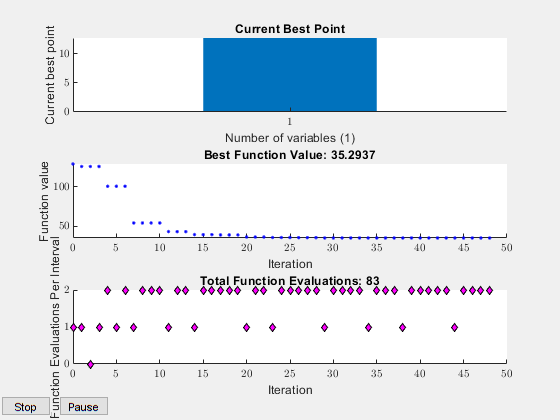

% Optimization for k - value 
% Find the optimal k where the sum of the maximum amplitude of both
% nutation and precession become the minimum
[k_opt,fval,exitflag,output] = HW9_P2_pattern_search_opt_k(6,5,20);

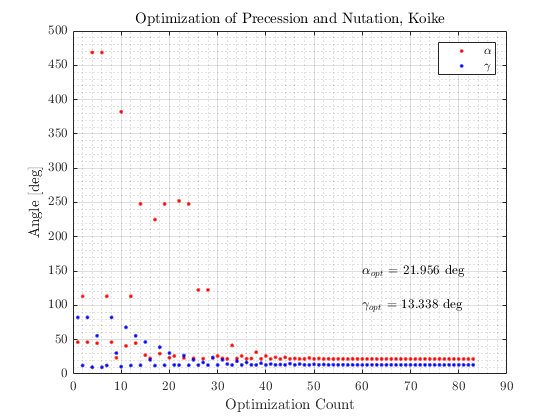

% Open created txt file with all the precession and nutation 
opt_data = readmatrix("inputs\opt_prec_nut_data.txt");
prec_opt = opt_data(:,1);
nut_opt = opt_data(:,2);
ct = 1:numel(prec_opt);

% Plot the transition of the optimization for the precession and nutation 
fig0 = figure("Renderer","painters");
    plot(ct,prec_opt,'.r',"MarkerSize",7)
    title("Optimization of Precession and Nutation, Koike")
    xlabel("Optimization Count")
    ylabel("Angle [deg]")
    hold on;
    plot(ct,nut_opt,'.b',"MarkerSize",7)
    hold off
    grid on; grid minor; box on;
    legend("$\alpha$","$\gamma$")
    t1 = sprintf("$\\alpha_{opt}$ = %.3f deg",prec_opt(end));
    t2 = sprintf("$\\gamma_{opt}$ = %.3f deg",nut_opt(end));
    text(60,150,t1);
    text(60,100,t2);
saveas(fig0,fullfile(fdir,"opt_prec_nut.png"));    

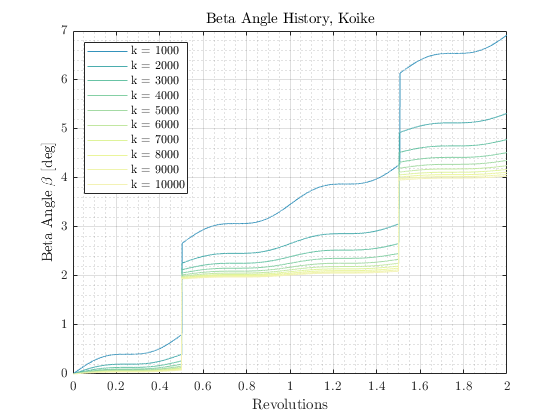

% Constant Inertial Precession
for j = 1:2
    close all;
    switch j
        % spin factors
        case 1
            k = 1e2:1e2:1e3;
        case 2
            k = 1e3:1e3:1e4;
        case 3
            k = 1e4:1e4:1e5;
    end
    for i = 1:length(k)
        % Nutation and Precession History
        [rev, Nut, Prec] = Nut_Prec_History(rev,k(i),gamma0,I,J);
        % Calculating Inertial Precession
        sigma = 360*rev;
        beta = Prec+sigma;
        % Plot Betas
        figure(2);
            hold on;
            plot(rev, beta, 'Color', rgb((i+j)*3,:), 'DisplayName',['k = ',num2str(k(i))])
    end
    % Saving Figures
    fig = figure(2);
        grid on; grid minor; box on; lgd = legend; xlabel('Revolutions');
        lgd.Location = "northwest";
        ylabel('Beta Angle $\beta$ [deg]')
        title({'Beta Angle History, Koike'})
        file_str = sprintf('P2c_Inertial_Precession_History_k=%d-%d.png', k(1),k(end));
        saveas(fig, fullfile(fdir, file_str));
end